# **Load and Extract Text Data**

Data = readtable("Training data.xlsx","TextType","string")

Data = 9417×2 table
             Measure_Name                                                                Description                                                   
    ______________________________    _________________________________________________________________________________________________________________

    "Bulb - Exterior"                 """"(1) 12w ledt8 lamp + 1l ballast lighting""""                                                                 
    "Bulb - Exterior"                 """"(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""""                                    
    "Bulb - Exterior"                 """"(1) 16.5w ledt8 lamp + 1h ballast lighting""""                                                               
    "Lighting Controls - Exterior"    """"(1) 2-pole circuit dimmer lighting""""                                                                       

# **Cross-Validation**

% Convert the labels in the PROGRAM column 
Data.Measure_Name=categorical(Data.Measure_Name)

Data = 9417×2 table
            Measure_Name                                                               Description                                                   
    ____________________________    _________________________________________________________________________________________________________________

    Bulb - Exterior                 """"(1) 12w ledt8 lamp + 1l ballast lighting""""                                                                 
    Bulb - Exterior                 """"(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""""                                    
    Bulb - Exterior                 """"(1) 16.5w ledt8 lamp + 1h ballast lighting""""                                                               
    Lighting Controls - Exterior    """"(1) 2-pole circuit dimmer lighting""""                                                                       
    VFD - C


% Partition data into sets for training and validation
cvp = cvpartition(Data.Measure_Name,"HoldOut",0.1,'Stratify',false)

cvp = Hold-out cross validation partition
   NumObservations: 9417
       NumTestSets: 1
         TrainSize: 8476
          TestSize: 941

dataTrain = Data(cvp.training,:)

dataTrain = 8476×2 table
            Measure_Name                                                               Description                                                   
    ____________________________    _________________________________________________________________________________________________________________

    Bulb - Exterior                 """"(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""""                                    
    Bulb - Exterior                 """"(1) 16.5w ledt8 lamp + 1h ballast lighting""""                                                               
    Lighting Controls - Exterior    """"(1) 2-pole circuit dimmer lighting""""                                                                       
    VFD - Cooling                   """"(1) 20 hp vfd on closed-circuit cooler fan motor cooling""""                                                 
    Ai

dataTest  = Data(cvp.test,:)

dataTest = 941×2 table
           Measure_Name                                                Description                                     
    ___________________________    ____________________________________________________________________________________

    Bulb - Exterior                """"(1) 12w ledt8 lamp + 1l ballast lighting""""                                    
    ECM Motor - HVAC               """"(1) grundfos alpha 15-55f ecm hw pump heating""""                               
    Furnace                        """"(12) heil model # n95esn080 2120a condensing furnaces, 96% efficient heating""""
    LED Linear - Upstream          """"(2) 10t8/48-4000-if-10/1 w/ (1) icn2p16tledn35m ele driver lighting""""         
    LED Screw In - Upstream        """"(2) 3.5w led candelabra screw-in lighting""""                                   
    LED Linear - Upstream          """"(2) 9t8led/36-4000-if-10/1 46


textDataTrain=dataTrain.Description  

textDataTrain = 8476×1 string array
    """"(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""""
    """"(1) 16.5w ledt8 lamp + 1h ballast lighting""""
    """"(1) 2-pole circuit dimmer lighting""""
    """"(1) 20 hp vfd on closed-circuit cooler fan motor cooling""""
    """"(1) air source heat pump cooling""""
    """"(1) air source heat pump heating""""
    """"(1) cm-9 & (1) pp-20 low voltage ceiling sensor lighting""""
    """"(1) cm-9 & (1) pp-20-2p low voltage ceiling sensor (2 circuits) lighting""""
    """"(1) door heater cntrl. (humidity sensor + control); (0) relays) refrigeration""""
    """"(1) door heater cntrl. (humidity sensor + control); (2 relays) refrigeration""""
    """"(1) door heater cntrl. (humidity sensor + control); (2) relays) refrigeration""""
    """"(1) dual enthalpy economizer cooling""""
    """"(1) dual tech wall sensor - 2 pole (includes the cost for the double gang satin stainless plate) lighting""""
    """"(1) ductless heat pump 

textDataTest=dataTest.Description

textDataTest = 941×1 string array
    """"(1) 12w ledt8 lamp + 1l ballast lighting""""
    """"(1) grundfos alpha 15-55f ecm hw pump heating""""
    """"(12) heil model # n95esn080 2120a condensing furnaces, 96% efficient heating""""
    """"(2) 10t8/48-4000-if-10/1 w/ (1) icn2p16tledn35m ele driver lighting""""
    """"(2) 3.5w led candelabra screw-in lighting""""
    """"(2) 9t8led/36-4000-if-10/1 469346 w/icn2p16tledn35m ele driver (2) lighting""""
    """"(2) air source heat pumps heating""""
    """"(2) cwp vfds cooling""""
    """"(2) espen ballasted 4' led t5 lighting""""
    """"(2) new track assemblies w/ (3) new 12w par30 led lamps each lighting""""
    """"(2) philips 10t8/48-4000-if-10/1 & (1) advance icn2p16tledn35m lighting""""
    """"(2) programmable thermostat cooling""""
    """"(4) 10t8/48-4000-if-10/1 468280 w/icn2p16tledn35m ele driver lighting""""
    """"(4) t5 led tube and ballast lighting""""
    """"(6) eco-optimizer demand control ventilation heating""""
    

YTrain = dataTrain.Measure_Name

YTrain = 8476×1 categorical array
     Bulb - Exterior 
     Bulb - Exterior 
     Lighting Controls - Exterior 
     VFD - Cooling 
     Air Source 
     Air Source 
     Lighting System - Exterior 
     Lighting System - Exterior 
     Hotel Occupancy Sensor 
     Hotel Occupancy Sensor 
     Hotel Occupancy Sensor 
     Economizer 
     Lighting System - Exterior 
     Ductless 
     Ductless 
     Lighting Fixture - Upstream 
     Lighting Fixture - Upstream 
     Furnace 
     Tankless Water Heater 
     Boiler 
     Tankless Water Heater 
     Lighting System - Exterior 
     LED Linear - Upstream 
     Variable Speed Drive 
     Lighting System - Interior 
     Lighting Fixture - Upstream 
     Economizer 
     Thermostat 
     Thermostat 
     Lighting Fixture - Upstream 
     LED Linear - Upstream 
     LED Linear - Upstream 
     LED Linear - Upstream 
     LED Screw In - Upstream 
     Circulator Pump 
     Lighting Fixture - Upstream 
     Lighting Fixture - Interior 
     

YValidation=dataTest.Measure_Name

YValidation = 941×1 categorical array
     Bulb - Exterior 
     ECM Motor - HVAC 
     Furnace 
     LED Linear - Upstream 
     LED Screw In - Upstream 
     LED Linear - Upstream 
     Air Source 
     VFD - Cooling 
     LED Linear - Upstream 
     LED Screw In - Upstream 
     LED Linear - Upstream 
     Thermostat 
     LED Linear - Upstream 
     LED Linear - Upstream 
     Demand Control Ventilation 
     Pipe Insulation - Hot Water 
     Door Heater Control 
     Sustainable Office Design 
     Novelty Cooler Control 
     Sustainable Office Design 
     Pipe Insulation - Hot Water 
     Pipe Insulation - Hot Water 
     Pipe Insulation - Hot Water 
     Fee 
     LED Linear - Upstream 
     LED Fixture - Upstream 
     Lighting Controls - Interior 
     Lighting Controls - Interior 
     Lighting System - Exterior 
     Lighting System - Exterior 
     Sustainable Office Design 
     LED Screw In - Upstream 
     LED Screw In - Upstream 
     Lighting Fixture - Upstream 
    

# **Preprocessing**

DATATrain_pre=preprocessText(textDataTrain)

DATATrain_pre =   8476×1 tokenizedDocument:

     9 tokens: 165w led instantfit tubes 1lamp none advance ballast lighting
     6 tokens: 165w ledt8 lamp 1h ballast lighting
     4 tokens: 2pole circuit dimmer lighting
     8 tokens: 20 hp vfd closedcircuit cooler fan motor cooling
     5 tokens: air source heat pump cooling
     5 tokens: air source heat pump heating
     7 tokens: cm9 pp20 low voltage ceiling sensor lighting
     8 tokens: cm9 pp202p low voltage ceiling sensor circuits lighting
     8 tokens: door heater cntrl humidity sensor control relays refrigeration
     8 tokens: door heater cntrl humidity sensor control relays refrigeration
     8 tokens: door heater cntrl humidity sensor control relays refrigeration
     4 tokens: dual enthalpy economizer cooling
    13 tokens: dual tech wall sensor pole includes cost double gang satin stainless plate lighting
     6 tokens: ductless heat pump lg #lsu180

DATATest_pre=preprocessText(textDataTest)

DATATest_pre =   941×1 tokenizedDocument:

     6 tokens: 12w ledt8 lamp 1l ballast lighting
     7 tokens: grundfos alpha 1555f ecm hw pump heating
    10 tokens: 12 heil model n95esn080 2120a condensing furnaces 96 efficient heating
     5 tokens: 10t8484000if101 icn2p16tledn35m ele driver lighting
     5 tokens: 35w led candelabra screwin lighting
     7 tokens: 9t8led 364000if101 469346 icn2p16tledn35m ele driver lighting
     5 tokens: air source heat pumps heating
     3 tokens: cwp vfds cooling
     5 tokens: espen ballasted led t5 lighting
     9 tokens: new track assemblies new 12w par30 led lamps lighting
     5 tokens: philips 10t8484000if101 advance icn2p16tledn35m lighting
     3 tokens: programmable thermostat cooling
     6 tokens: 10t8484000if101 468280 icn2p16tledn35m ele driver lighting
     5 tokens: t5 led tube ballast lighting
     5 tokens: ecooptimizer demand control ventilation heating
   

enc =   wordEncoding with properties:

      NumWords: 5960
    Vocabulary: [1×5960 string]


dataLengths = doclength(DATATest_pre)

dataLengths =      6
     7
    10
     5
     5
     7
     5
     3
     5
     9


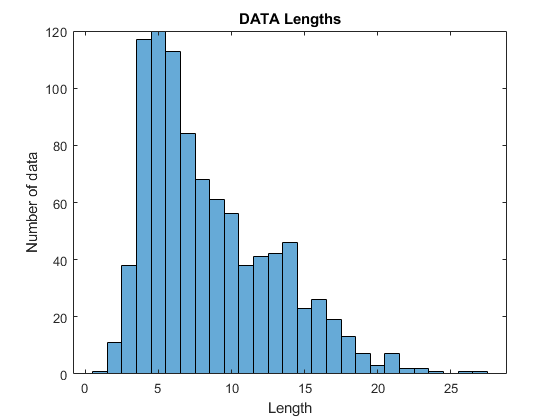

figure
histogram(dataLengths)
title("DATA Lengths")
xlabel("Length")
ylabel("Number of data")

% Choose target length
sequenceLength = 18

sequenceLength = 18

# **Convert Data to Sequences**

enc = wordEncoding(DATATrain_pre)

XTrain = doc2sequence(enc,DATATrain_pre,...

XTrain = 8476×1 cell array
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
 

                     'Length',sequenceLength)
XValidation = doc2sequence(enc,DATATest_pre,...
                           'Length',sequenceLength);

# **Create and Train LSTM Network**

% Define the LSTM network architecture
inputSize = 1;
embeddingDimension = 50;
numHiddenUnits = 80;

numWords = enc.NumWords;
numClasses = numel(categories(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   6x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 5960 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         128 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

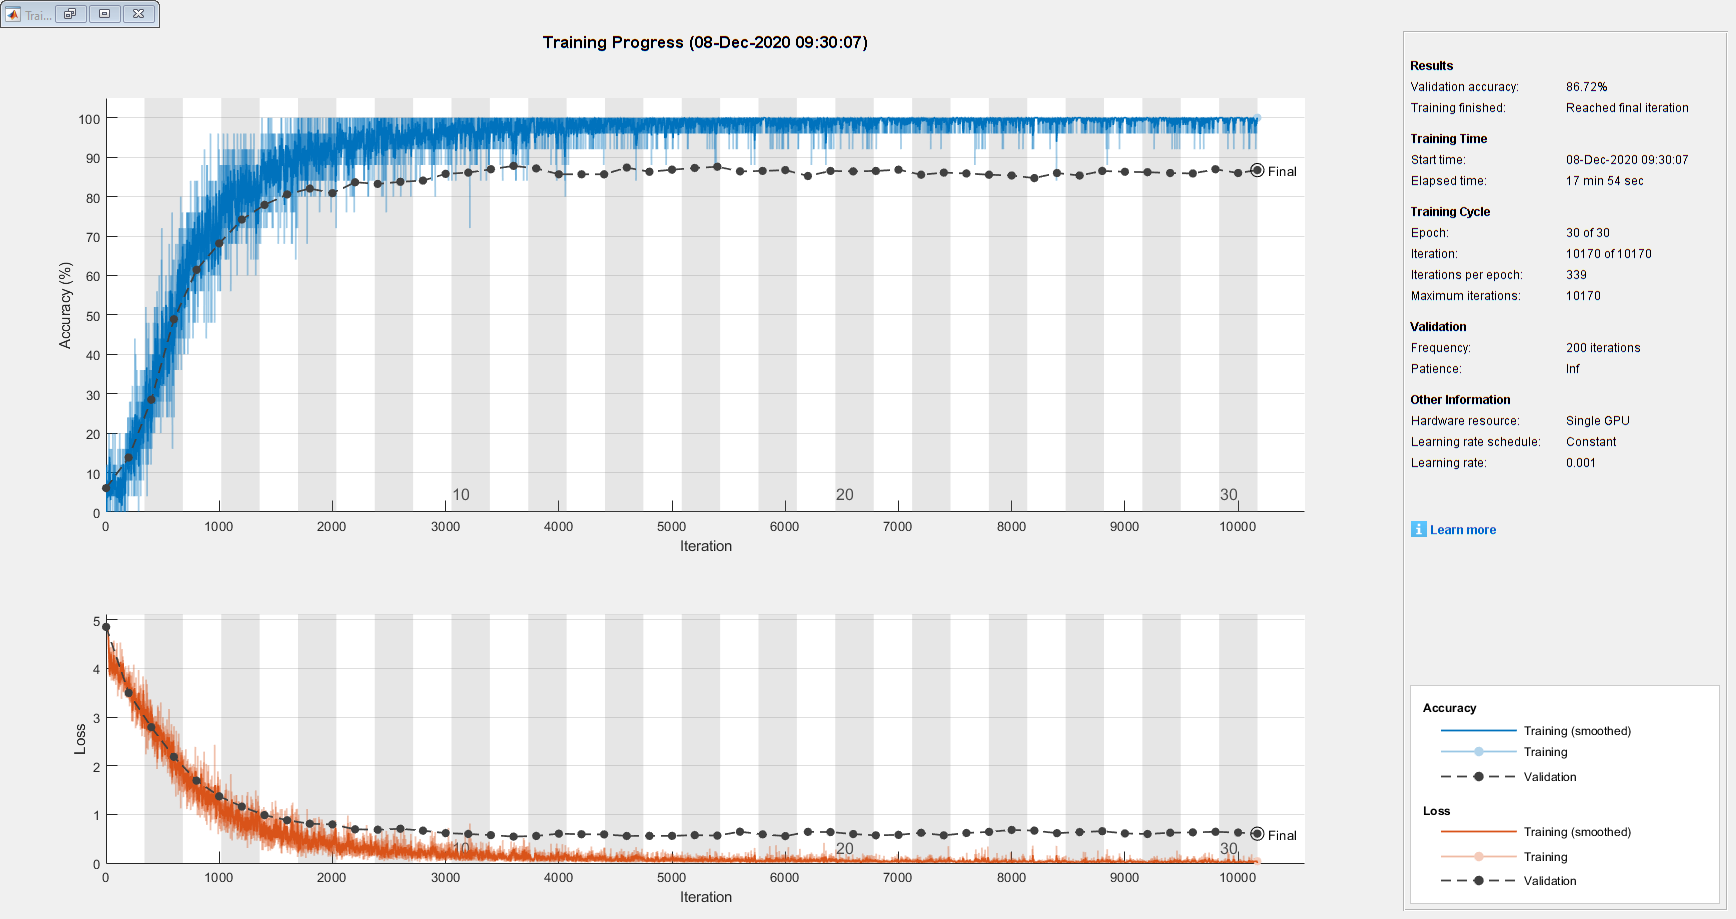


% Specify Training Options
options = trainingOptions('adam', ...
    'MiniBatchSize',25, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    "ValidationFrequency",200,...
    'ValidationData',{XValidation,YValidation}, ...
    'Plots','training-progress', ...
    'Verbose',false);

net = trainNetwork(XTrain,YTrain,layers,options);

# **Predict Using New Data**

Newtest=readtable("Total_Data.txt","TextType","string")

Newtest = 4883507×3 table
                                           PROGRAM_NAME                                            STATE                                                                      Characterization                                                                   
    ___________________________________________________________________________________________    _____    _____________________________________________________________________________________________________________________________________________________

    "Retrofit"                                                                                     "MA"     "industrial processing | vsd | variable speed drives (non-hvac systems) | custom vsds |  |  | process"                                               
    "| Retrofit |  | MOU |  |  |  |  |  |  |"                                                    

Newtest=rmmissing(Newtest)

Newtest = 4883507×3 table
                                           PROGRAM_NAME                                            STATE                                                                      Characterization                                                                   
    ___________________________________________________________________________________________    _____    _____________________________________________________________________________________________________________________________________________________

    "Retrofit"                                                                                     "MA"     "industrial processing | vsd | variable speed drives (non-hvac systems) | custom vsds |  |  | process"                                               
    "| Retrofit |  | MOU |  |  |  |  |  |  |"                                                    

dataNew = preprocessText(Newtest.Characterization);

XNew = doc2sequence(enc,dataNew,'Length',sequenceLength)

XNew = 4883507×1 cell array
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}
    {1×18 double}


Measure_Name  = classify(net,XNew)

Measure_Name = 4883507×1 categorical array
     Variable Speed Drive 
     Lighting System - Custom 
     Compressed Air - Custom 
     Comprehensive Design 
     Energy Management System 
     Comprehensive Design 
     Variable Speed Drive 
     Lighting System - Custom 
     Lighting System - Custom 
     HVAC - Custom 
     Lighting System - Custom 
     Lighting System - Custom 
     Variable Speed Drive 
     Lighting System - Custom 
     Lighting System - Custom 
     Lighting System - Custom 
     Process - Custom 
     LED Fixture - Upstream 
     HVAC - Custom 
     ECM Motor - HVAC 
     Fluorescent - Upstream 
     EC Motor 
     EC Motor 
     LED Fixture - Upstream 
     LED Linear - Upstream 
     LED Fixture - Upstream 
     Variable Speed Drive 
     Performance Lighting - Tier 1 
     Energy Management System 
     Lighting System - Custom 
     Air Compressor 
     LED Linear - Upstream 
     LED Fixture - Upstream 
     LED Screw In - Upstream 
     Lighting System


Result=table(Measure_Name,Newtest.PROGRAM_NAME,Newtest.STATE,Newtest.Characterization)

Result = 4883507×4 table
          Measure_Name                                                     Var2                                                Var3                                                                            Var4                                                                         
    ________________________    ___________________________________________________________________________________________    ____    _____________________________________________________________________________________________________________________________________________________

    Variable Speed Drive        "Retrofit"                                                                                     "MA"    "industrial processing | vsd | variable speed drives (non-hvac systems) | custom vsds |  |  | process"                               

writetable(Result)

function predata = preprocessText(textData)

predata=lower(textData);
predata=strtrim(predata);
predata=tokenizedDocument(predata);
predata=erasePunctuation(predata);
predata=removeStopWords(predata);
predata=removeShortWords(predata,1);

end